# Executing GSPNRs

The package provides a class named ExecutableGSPNR that can execute a multi-robot system modelled by a GSPNR, by interfacing with user-defined [ROS action servers](http://wiki.ros.org/actionlib). This module utilizes the [ROS toolbox](https://www.mathworks.com/products/ros.html) to communicate with the action servers.

This example requires setting up your ROS workspace beforehand. Please make sure you have followed the steps in the [Home Scenario](matlab:open('./HomeScenario.mlx')) before going through the tutorial.

### Overview

The execution functionality is implemented by mapping tokens in the GSPNR with individual robots, and where certain places in the GSPNR (from now on denominated *action places*) correspond to task being executed by the robot represented by the token currently in that place.

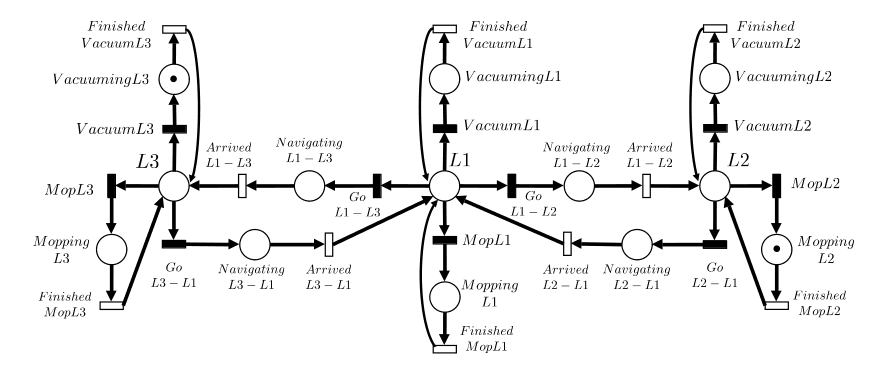

Using the example above, two places are marked: "VacuumingL3" and "MoppingL2", and so if these places are *action places*, a goal would be sent to a corresponding action server, for the correct robot represented by the tokens currently in each place.

The workflow for converting your GSPNR models into executable ones is the following:

- Creating an empty ExecutableGSPNR model and initializing it;

- Setting the policy;

- Adding robots;

- Creating the ROS interface package;

- Executing.

#### **To run the example of this module, its recommended to not run the code snippets in this live script, but the one **[**here**](matlab:open('./ExampleExecuting.mlx'))**.**

## 1) Using a GSPNR object to initialize an ExecutableGSPNR

To create a GSPNR that can be executed, you must first instantiate an empty ExecutableGSPNR object, and then initialize it with an existing GSPNR object:

ExecutableHome = ExecutableGSPNR();

After creating an empty object, it must be initialized using the initialize() class method. This methods copies the entire GSPNR object into the ExecutableGSPNR instance

yaml_filepath = 'home_example.yaml';
ExecutableHome.initialize(home_GSPNR, yaml_filepath, []);

This method takes as input either a YAML file referenced by its path, or a structure. An example of the YAML file used in the GSPN in the figure above (that models the cleaning scenario) can be found [here](matlab:open('./extra_examples/execution_examples/config/YAML/home_example.yaml')).

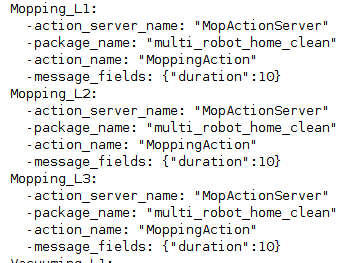

Each element of the YAML file must correspond to a place in the executable model, and it must have the fields seen in the figure above:

- **action_server_name**: the name of the action server that implements the task with the name registered in the ROS master;

- **package_name**: the name of the ROS package where the action server is found;

- **action_name: **the name of the action used by the ROS action server;

- **message_fields: **a dictionary containing all the message fields and their corresponding values needed in order to build the goal message that your ROS Action Server accepts.

If you prefer not to use YAML files, or are creating the executable model programatically, you can use the third input of the initialize method, and must leave the second one as an empty array.

This **action_map** input is a structure, where each fieldname is the name of the *action place*, and it points to a structure with with the following fields: **action_server_name**, **package_name**, **action_name**, **message_fields**. An example would be the following (for only one *action place* - "Mopping_L1"):

action_map.Mopping_L1.action_server_name = "MopActionServer";
action_map.Mopping_L1.package_name = "MopActionServer";
action_map.Mopping_L1.action_name = "MopActionServer";
action_map.Mopping_L1.message_fields = struct(duration,10)

ExecutableHome.initialize(home_GSPNR, [], action_map);

## 2) Setting the ExecutableGSPNR Policy

policy_workspace_filepath = 'policy_home_example_with_timeouts.mat';
load(policy_workspace_filepath, 'complete_policy');

To set up a policy, the set_policy() method needs to be used. It takes as input a policy structure variable exactly as output by the policy synthesis module:

ExecutableHome.set_policy(complete_policy);

If you need to use a handcrafted policy, you can manually set the policy property of the executable model using the method set_manual_policy:

ExecutableHome.set_manual_policy(markings, transitions);

Here the inputs are the following:

- **markings - **an integer array, where each row vector is a marking in the ExecutableGSPNR that you want to set the policy for;

- **transitions - ** a string array, the same length as the second dimension of **markings, **such that the i-th element of the **transitions** array corresponds to the transition that should be fired when the current marking of the GSPNR is equal to the marking in the i-th row of the **markings** input.

Care should be taken to not have duplicate markings in the handcrafted policy.

## 3) Adding Robots

To add robots to your executable model, the add_robots() method must be used:

ExecutableHome.add_robots(["robot_0", "robot_1"], ["L1", "L1"]);

The first input is a string array containing the namespaces of each robot that is to be added, and the second input is a string array with each robot's initial location in the model.

As each robot has its own action servers, normally with the same name, ROS namespaces have to be used. In the figure below, you can see that each robot has its own set of action servers with the same names, but in different namespaces. By inputting the namespaces of each robots, the execution method can identify to which action server to send the goal, when a particular token/robot is in an action place.

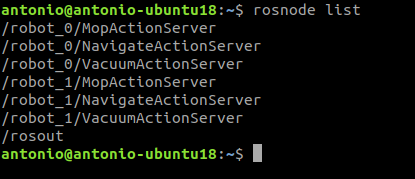

The second input is used to initialize the mapping between token and robots, so that the execution method can unequivocally identify each token to a single robot.

## 4) Execution

Before executing, an interface ROS package needs to be built. This ROS package needs to be located in your catkin workspace, and by default it uses the path indicated by your CMAKE_PREFIX_PATH environment variable. If either this variable is not set, or you wish to use another location, you can set up the location of the desired catkin workspace using the set_catkin_ws() class method:

ExecutableHome.set_catkin_ws('catkin_ws')
ExecutableHome.create_ros_interface_package(true)

The create_ros_interface_package() function takes a single output that can be either true or false, to suppress or allow output to the command window from catkin.

After creating the interface ROS package, the model is ready to be executed:

ExecutableHome.start_execution();

### IMPORTANT: in some machines, MATLAB cannot run *roslaunch* from inside the MATLAB environment. And so you must manually launch the interface action servers which will connect the executable model running in MATLAB and your ROS Action Servers. This is done by running the following command in a terminal before starting the execution class method: